# Proyecto Final 

## Algoritmos númericos por computadora

#### Cecilia Vásquez 150482

#### Maritrini Garcia 151490


$$y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack$$
 
$$y^{\prime } =\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$$



$$\frac{\textrm{d}}{\textrm{d}t}y=f\left(t,y\right)$$


Para la resolución de los siguientes problemas se toma en cuenta la **Ley gravitacional, **para un resultado adecuado se tomaron los valores reales que se obtuvieron a través de una búsqueda en internet de la masa y radio de la tierra, así como la del sol y la luna.

Para el valor de la constante de gravtiación (G) se utilizo el valor dado por la CODATA (*committee on data for science and technology) *este valor tiene una incertidumbre estándar de `0.000 15 x 10-11 m3 kg-1 s-2`

# Tierra y luna

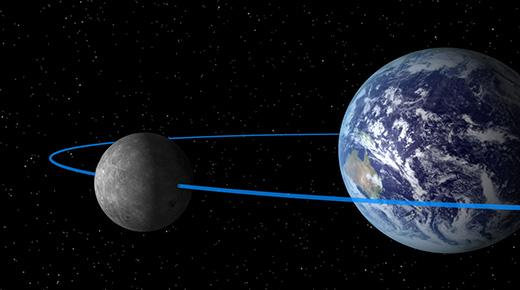

Para la resolución de este caso se toma de referencia el centro de la tierra.

El radio de la tierra se utilizará en metros al igual que el de la luna.

A continuación se declaran las variables a utilizar en la resolución del problema

global G masas;
G=  6.67430E-11;
mTierra = 5.972E+24;
mLuna = 7.349E+22;
masas = [mTierra, mLuna]; % vector con las masas
radioT = 6371000; %m
radioL = 1737100; %m
distanciaTL = 384400000; %m

El siguiente paso es crear el vector de posiciones iniciales de la tierra y la luna, en la primera columna se encontrarán las de la tierra y en la segunda las de la luna, dicho vector se llamará r0.

r0 = [[0; 0 ; 0] , [radioT + distanciaTL + radioL; 0;0]];

Se calcula la velocidad inicial de la luna:

VelL= sqrt(G*masas(1)/r0(1,2));
v0= [[0;0;0], [0;VelL;0]];
h = 60;        %longitud de intervalo                  
vueltas = 3; %numero de vueltas

se calcula la frecuencia de la orbita de la luna con respecto a la tierra, para esto se utiliza la siguiente formula: 

$\mathrm{frec}=\frac{\mathrm{velocidad}}{\mathrm{lambda}}$ donde lambda es la longitud de la onda que en nuestro caso es : radio de la tierra + distancia de la tierra a la luna.

ws = VelL/(radioT+distanciaTL);
periodo = (2*pi)/ws; %velocidad angular
totV = vueltas*ceil(periodo/h);  %total de vueltas tomando en cuenta el periodo y el intervalo de longitud


Ahora se calcula el vector de posiciones con lo calculado anteriormente

pos = zeros(6,totV+1);     
pos(:,1) = [r0(:,1);r0(:,2)];       
y = [r0;v0];



Se utilizará el método de RK4 para poder resolver las ecuaciones. Se decidio utilizar este método ya que tiene un error menor que el del euler, pero esto depende de las condiciones iniciales y las ecuaciones diferenciales a resolver también si tenemos un polinomio  de orden n este seria más preciso con un método n- Runge-Kutta por ejemplo Euler será exacto si  la solución es lineal y rk4 si el polinomio es de grado 4 o menor.

 
for t=2:totV+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    pendiente = (s1+2*s2+2*s3+s4)/6;
    y = y + pendiente*h;            
    r = y(1:3,:);               
    pos(:,t) = [r(:,1);r(:,2)];    
end

Graficas:

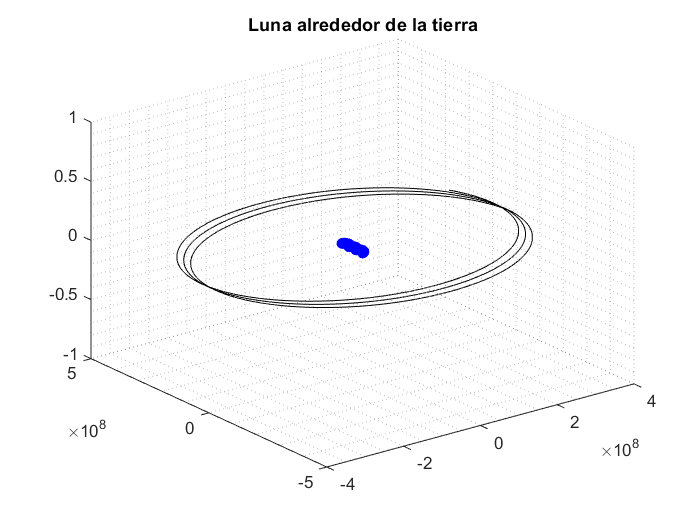

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'k');
title('Luna alrededor de la tierra')
grid minor;
hold off

## Calculo de la velocidad y aceleración para 2 cuerpos

function velAc = f(~,y)
global G masas;
r = y(1:3,:);       % Posiciones de los 2 cuerpos
v = y(4:6,:);       % velocidades de los 2 cuerpos
dist = r(:,2) - r(:,1); %distancia entre los cuerpos
u = dist / norm(dist); % vector unitario
distcuad = norm(dist)^2;  %distancia al cuadrado
F = ((G*masas(1)*masas(2))/distcuad) * u; % ley de gravitación universal
a = [F/masas(1), - F/masas(2)]; % vector de aceleraciones
velAc = [v;a];
end

## Calculo de velocidad y aceleración para 3 cuerpos

function velAc = f1(~,y)
global G m;
r = y(1:3,:); %posiciones de los 3 cuerpos
v = y(4:6,:); % velocidades de los 3 cuerpos
d21 = r(:,2) - r(:,1); % distancia del cuerpo 2 al 1
d31 = r(:,3) - r(:,1); % distancia del cuerpo 3 al 1
d32 = r(:,3) - r(:,2); % distancia del cuerpo 3 al 2

% vectores unitarios
u1 = d21 / norm(d21);
u3= d31 / norm(d31);
u2= d32 / norm(d32);

%distancias al cuadrado
d12 = norm(d21)^2;
d32 = norm(d31)^2;
d22 = norm(d32)^2;

%fuerzas de los 3 cuerpos
F12= (G*m(1)*m(2)/d12) * u1;
F23= (G*m(1)*m(3)/d32) * u3;
F13= (G*m(2)*m(3)/d22) * u2;

Fs = F12 + F13;
Ft = -F12 +FtVF13;
Fv = -F23 - F13;

a = [Fs/m(1), Ft/m(2), Fv/m(3)];
velAc = [v;a];
end